NifTI files are used to store images of brain scans taken with MRI machines. 

This livescript will explore what is in a typical NifTI file, as well as demonstrate basic plotting functions in Matlab. 

Data is from https://openneuro.org/datasets/ds000228/versions/1.1.1

***Warning!*** You will need the Image Processing Toolbox. If its not already installed, it can be in a few clicks after running the cell below

Firstly, let's examine the header. 

file = 'sub-pixar023/func/sub-pixar023_task-pixar_bold.nii.gz'; % gz extraction done automatically
info = niftiinfo(file);

info.raw

ans = struct with fields:
        sizeof_hdr: 348
          dim_info: '9'
               dim: [4 64 64 32 168 0 0 0]
         intent_p1: 0
         intent_p2: 0
         intent_p3: 0
       intent_code: 0
          datatype: 4
            bitpix: 16
       slice_start: 0
            pixdim: [-1 3 3 3.3000 2 0 0 0]
        vox_offset: 352
         scl_slope: 1
         scl_inter: 0
         slice_end: 0
        slice_code: 2
        xyzt_units: 10
           cal_max: 0
           cal_min: 0
    slice_duration: 0
           toffset: 0
           descrip: 'TE=30;Time=103556.212;phase=1;dwell=0.500'
          aux_file: 'imgComments'
        qform_code: 1
        sform_code: 1
         quatern_b: -0.0373
         quatern_c: 0.9912
         quatern_d: -0.1170
         qoffset_x: 100.5703
         qoffset_y: -60.3081
         qoffset_z: -18.6319
            srow_x: [-2.9773 -0.1877 -0.3482 100.5703]
            srow_y: [-0.2563 2.9096 0.7531 -60.3081]
            srow_z: [-0.2641 -0.7065 3.19

The most important information is the dim info. This tells us the dimensions of the MRI data. 

The first number reveals the dimensionality of the data, in this case 4. Thus the data is described by the 4 following numbers. The last three fields are ignored.

The next two give the dimensions of the images themselves. Here we see the images are 64 x 64 pixels. 

Next we have the number of images in the z direction - here we have 32 slices of the brain. 

Lastly there is the temporal variations - we have 168 separate points in time at which images were recorded.

To summarise:

## Accessing Data

The images are stored as an array. To work with the 6th image in the z-direction taken at the first time epoch, do 

V = niftiread(file);
img = V(:,:,6,1);
img

img = 64×64 int16 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
   23   33   26   28   42   32   31   27   28   34   34   36   31   43   31   39   35   40   36   36   36   29   35   40   32   36   28   31   38   46   31   38   30   36   35   36   36   41   34   27   32   29   36   30   50   32   28   36   42   33
   32   47   38   30   42   30   32   27   45   26   42   36   34   46   28   27   33   39   35   30   38   32   31   31   36   33   35   39   24   36   31   33   31   29   26   39   28   34   33   32   27   35   39   32   41   32   35   35   36   42
   30   37   38   30   46   27   30   35   35   32   25   30   32   34   32   47   39   28   38   38   32   43   29   30   37   38   32   45   39   35   36   35   37   35   33   31   31   41   43   33   34   27   35   34  

we can see this is a square array of size 64, as expected from the header.

Viewing the image is simple: 

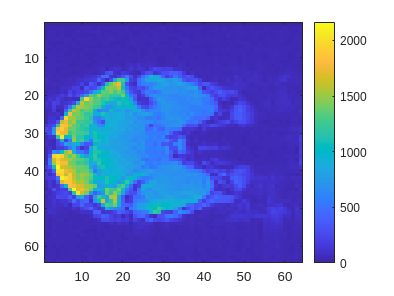

image(img,'CDataMapping','scaled')
colorbar

## Extracting Statistics

Which slice of the brain is the most active at the first time epoch? Let's average across all 32 images

imgs = V(:,:,:,1);
imgs_mean = mean(imgs, [1,2]); % average over 1st and 2nd dimensions. Here x and y of image plane
imgs_mean = reshape(imgs_mean,1,[]); % reshape to 1D array

Now make a plot of the averages

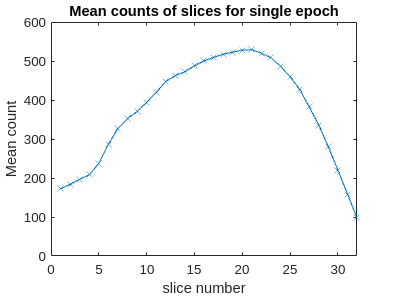

h = plot(imgs_mean,"LineStyle","-",...
"Marker","x");

ylabel("Mean count")
xlabel("slice number")
title("Mean counts of slices for single epoch")

Is there a point in time at which the brain was most active? Let's now average over time

time_avg = mean(V, [1,2,3]);
time_avg = reshape(time_avg,1,[]);

A plot can also be made using the interactive Create Plot  - **SO EASY!**

## Time of image acquisition

That's nice but we still don't know anything about the time resolution of the images. This information is stored in a json file.

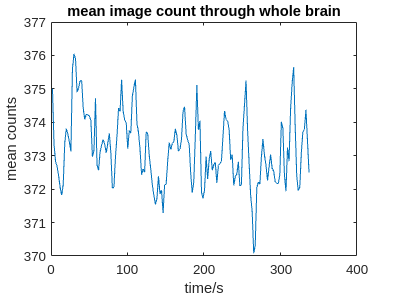

text = fileread("sub-pixar023/func/sub-pixar023_task-pixar_bold.json");
data = jsondecode(text);

times = data.time.samples.CsaImage_TimeAfterStart;

h3 = plot(times,time_avg,"DisplayName","time_avg");

% Add ylabel, title, and legend
ylabel("mean counts")
xlabel("time/s")
title("mean image count through whole brain")

## Thoughts

How do you interpret the plot of mean counts vs. time? 

Is mean counts the best metric for brain activity? 

Let's investigate the maximum count for each time epoch

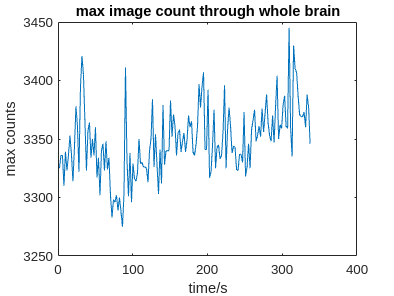

res =[];
%should be possible usine max function, but I couldn't do it
for i =1: size(V, 4) % loop over time dim.
    vv = V(:,:,:,i);
    vv_max= max(vv,[],[1,2,3]);
    vv_max = reshape(vv_max,1,[]);
    res = [res; vv_max];
end

plot(times,res);
ylabel("max counts")
xlabel("time/s")
title("max image count through whole brain")

## Interactive plot with slider

When the two sliders are moved, the plotted data is changed. NB. only works in Matlab live script

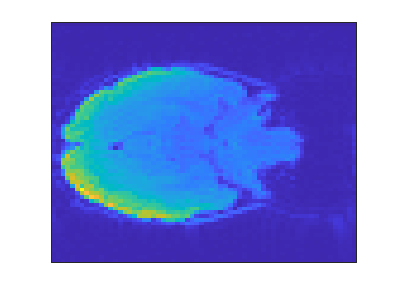

slice_num = 10;
time_index = 110;
im1 = image(V(:,:,slice_num,time_index),'CDataMapping','scaled');
set(gca,'XTick',[], 'YTick', []) % remove axis tick labels